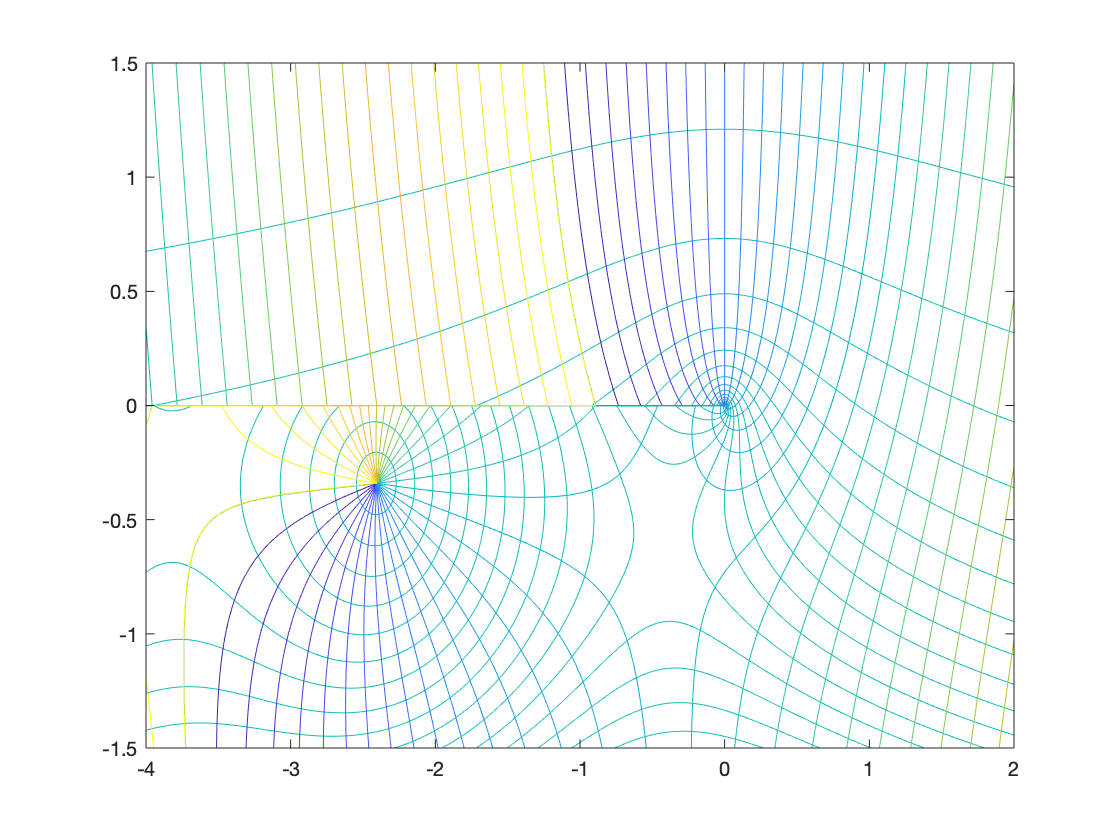

[X,Y] = meshgrid(-4:0.002:2,-1.5:0.002:1.5);

H = besselh(0,X+1i*Y);
contour(X,Y,abs(H),0:0.2:3.2)
hold on

contour(X,Y,rad2deg(angle(H)),-180:10:180)
hold off

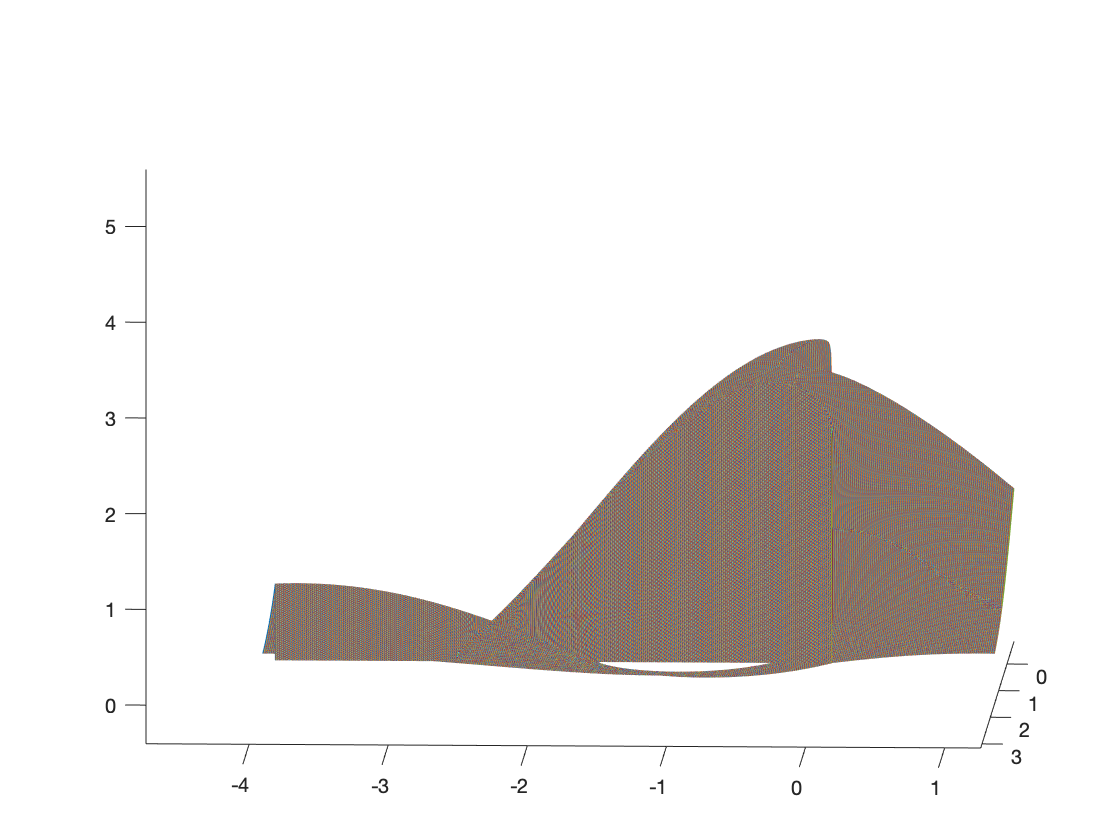


plot3(X,Y,H)

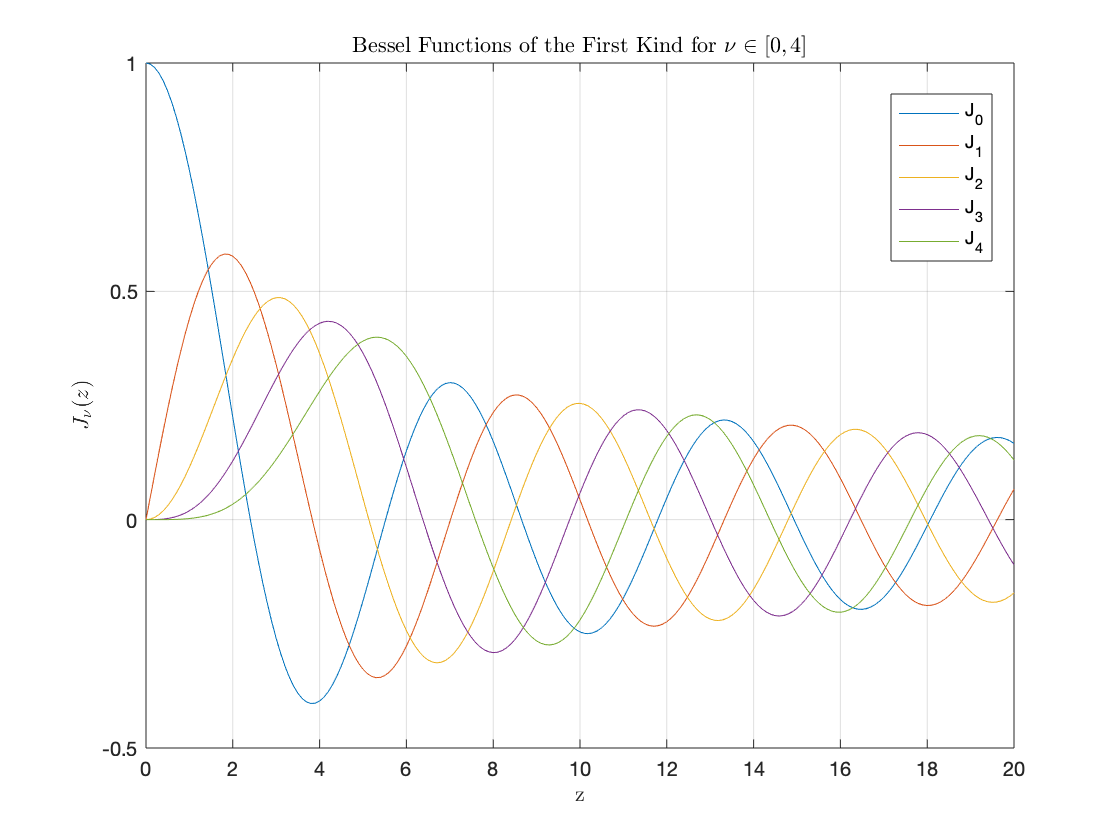


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

J = zeros(5,201);
for i = 0:4
    J(i+1,:) = besselj(i,z);
end

plot(z,J)
grid on
legend('J_0','J_1','J_2','J_3','J_4','Location','Best')
title('Bessel Functions of the First Kind for $\nu \in [0, 4]$','interpreter','latex')
xlabel('z','interpreter','latex')
ylabel('$J_\nu(z)$','interpreter','latex')